**General Information**

The Radar class is to create instances of radar objects that are placed within the simulation that is to detect air traffic within the lane based system. The main function in this class is to scan the environment given a certain radar field if their is any objects in its view. If any objects are detected during a scan, the radar object will broadcast that an object has been detected.

Each radar object has multiple different properties: location coordinates, direction coordinates, maximum range, the beam width angle (apexAngle/2), an identification number, and a handle to the simulator. 

**Simulation Set Up **

This portion of the code, sets up all the objects that are needed in the simulation to deminstrate the functionality of the radar object. 

%%%%%%%%%%%%%%%%%%%%%% LANE BASED SYSTEM SETUP %%%%%%%%%%%%%%%%%%%%
lbsd = LBSD.genSampleLanes(10, 15);
lbsd.makeReservation("8", 0, 10, 1, 5, "1");
reservations = lbsd.getLatestRes;
disp(reservations);

    id     lane_id    uas_id    entry_time_s    exit_time_s    speed    hd
    ___    _______    ______    ____________    ___________    _____    __

    "1"      "8"       "1"           0              10           1      5 




%%%%%%%%%%%%%%% UAS SETUP %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
id = reservations(1, :).uas_id;
uas = UAS(id);

pos = lbsd.getVertPositions(lbsd.getLaneVertexes(reservations(1, :).lane_id));
uas.gps.lon = pos(1, 1);
uas.gps.lat = pos(1, 2);
uas.gps.alt = pos(1, 3);

% Setting up the trajectory
drone_time = reservations.entry_time_s;
end_time = reservations.exit_time_s;
steps = pos(1, :);
dis = pos(2, :) - pos(1, :);
dir = dis/norm(dis);
while (drone_time < end_time)
    cur_pos = steps(end, :);
    x = cur_pos(1) + dir(1)*rand()*.3;
    y = cur_pos(2) + rand();
    y = y - rand();
    z = cur_pos(3);
    steps = [steps; x, y, z];
    drone_time = [drone_time; (drone_time(end, 1) + .1)];
end

%%%%%%%%%%%%%%%%%% SIMULATION OBJECT %%%%%%%%%%%%%%%%%%%%%%%%%%%%
sim = Sim(); 
sim.uas_list = uas;

**Creation of a Radar Object**

To create an radar object, the constructor needs: the location of the radar as a 1x3 vector; the maximum range the radar field can reach as a float; the beam width angle which is the angle of the radar field from the middle of the cone to the side of the radar field as a float; the direction unit vector in which way the radar field is pointing as a 1x3 vector; the identification number as a string, and finally the lbsd object handle.

location = [pos(1, 1:2), 0]; % x, y, z coordinates
range = 30; % Max Range
angle = pi/4; % angle between mid cone to side cone 
dir = [0,0,1]; % radar direction unit vector
ID = "1"; 

radar = RADAR(location, range, angle, dir, ID, lbsd);
radar.time = 0;
sim.subscribe_to_tick(@radar.handle_events);

**Scaning the Simulation**

The main function the radar object is to be able to scan the simulation and detect objects that are within its radar field view. The way this method works, is that with each time step in the simulation, the sim object will pass the "actual" positions of all the uas objects that are currently in flight in the environment. The radar object will loop through all the uas objects and check to see if they are within its view. If it detects the object, then it will broadcast to any listening objects.

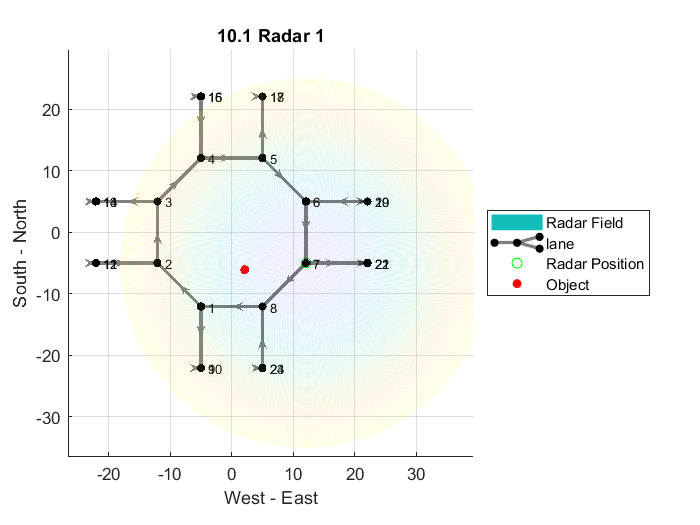

%%%%%%%%%%%%%%%%%%%%%%% SCANNING THE ENVIRONMENT %%%%%%%%%%%%%%%%%%%%%%%
radar.showDetection(); % Will show the radar detection

for t = 1:size(steps, 1) % Go through each time loop
    % Move each uas in the environment
    uas.gps.lon = steps(t, 1);
    uas.gps.lat = steps(t, 2);
    uas.gps.alt = steps(t, 3);
    
    % Update the UAS position in the simulation list
    sim.uas_list = uas;
    sim.step(.1);
    M(t) = getframe(radar.scanData.fHandle); % Sets up a movie object that will display
end

**Displaying the Radar Field Scanning**

The live function doesn't support movie function, so the movie object has been set up and can be displayed by typing movie(M) in the command window. 